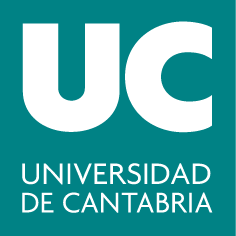

#### ***Grado en Ingeniería Química***

## **G320: Álgebra**

# **Práctica 2: Trabajo con matrices**

*Rodrigo García Manzanas (rodrigo.manzanas@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es)*

**Objetivos**

- Calcular la forma escalonada reducida y el rango de una matriz 

- Calcular la factorización de matrices LU y la de Cholesky

**Forma escalonada reducida (y rango) **

Sea la matriz $A$ =$\left\lbrack \begin{array}{cccc}
-2 & 0 & 0 & 0\\
1 & 0 & 0 & 0\\
2 & 0 & -1 & 2\\
5 & 0 & 1 & 2
\end{array}\right\rbrack$

A = [-2 0 0 0; 1 0 0 0; 2 0 -1 2; 5 0 1 2];  % defino la matriz A

El comando *rref *permite encontrar su forma escalonada reducida (por filas):

Ared = rref(A)  % Ared es la forma reducida por filas 

*rref *admite un segundo argumento de salida que nos devuelve un índice que identifica a las columnas pivotales:

[Ared, cp] = rref(A)  % cp es un vector que contiene los índices que % identifican las columnas pivotales

Por tanto, el rango de la matriz $A$ puede obtenerse fácilmente a partir de este vector de índices:

length(cp)  % rango(A) = número de columnas pivotales de Ared

De todos modos hay un comando que permite calcular directamente el rango de cualquier matriz, *rank*:

rank(A)  % rango(A) = 3

**Factorización PA=LU**

Dada una matriz $A_{m \times n}$, el comando *lu* de MATLAB permite hallar **una** factorización del tipo $PA=LU$, en la que $L_{m \times m}$ es una matriz triangular inferior con unos en la diagonal, $U_{m \times n}$ es una forma escalonada de $A$ y $P_{m \times m}$ es una matriz de permutaciones que recoge los intercambios de filas que tienen lugar durante el proceso de escalonamiento. Recuerda que este tipo de factorización **no es única.**

A = [0 4 -3 2; 1 2 1.5 3; 5 5 1 4]  % matriz a factorizar (no tiene por qué ser cuadrada)
[L, U, P] = lu(A)  % P es la matriz de permutaciones necesaria para que PA = LU
P*A - L*U   % comprobación

**Factorización de Cholesky**

MATLAB también dispone de un comando específico para el cálculo de la factorización de Cholesky, *chol. *Como ya se ha visto, este tipo de factorización sólo se puede aplicar en el caso de matrices reales simétricas (por tanto, cuadradas) y definidas positivas. Creemos por tanto, en primer lugar, una matriz de este tipo:

A = [2 1 0 0; 1 4 1 0; 0 1 4 1; 0 0 1 2]  % matriz 4x4 simétrica definida positiva
issymmetric(A)  % operador booleano (ó lógico) que me dice si una matriz dada es simétrica (1) o no (0)
[det(A(1,1)), det(A(1:2, 1:2)), det(A(1:3, 1:3)), det(A)]  % todos los menores principales son positivos -> definida positiva

Aplicamos ahora el comando *chol* para la factorización Cholesky:

L = chol(A, 'lower')  % matriz que necesitamos para la factorización de Cholesky

La matriz $L$ que hemos hallado debe cumplir la relación $A=LL^t$. Comprobémoslo:

A - L*L'  % comprobación 

***Nota***: El argumento de entrada opcional "lower" fuerza que la matriz de salida $L$ sea triangular inferior y verifique $A = LL^t$. Por defecto, defecto, el comando *chol* utiliza el argumento "upper", que da lugar a una matriz triangular superior, $U$, en cuyo caso la factorización resultante sería $A = U^tU$.

Ten en cuenta que si la matriz de partida no fuera simétrica y definida positiva, el comando *chol* seguirá operando sin dar lugar a un error. Sin embargo, la matriz devuelta en este caso no cumplirá que $A = LL^t$

A = [2 1 0 0; 1 4 1 0; 0 1 4 1; 0 0 -1 2]  % matriz 4x4 NO simétrica 
issymmetric(A)  % operador booleano (ó lógico) que me dice si una matriz dada es simétrica (1) o no (0)
det(A(1,1)), det(A(1:2, 1:2)), det(A(1:3, 1:3)), det(A)  % todos los menores principales son positivos -> definida positiva
L = chol(A, 'lower')  % aplico el comando "chol"
A - L*L'  % no se cumple que A = L*L'

#### Ejercicios propuestos

**Ejercicio 1:**

Encuentra una factorización del tipo $PA = LU$ para las siguientes matrices y utiliza dicha factorización para calcular su determinante y su inversa (si la hubiera):


$$A=\left\lbrack \begin{array}{ccc}
1 & -2 & 3\\
2 & -6 & 5\\
-1 & -4 & 0
\end{array}\right\rbrack$$
                
$$B=\left\lbrack \begin{array}{ccc}
1 & -2 & 3\\
3 & -6 & 9\\
2 & -3 & 1
\end{array}\right\rbrack$$


**Ejercicio 2:**

Si se puede, factoriza según Cholesky las siguientes matrices y utiliza dicha factorización para calcular su determinante y su inversa:


$$A=\left\lbrack \begin{array}{ccc}
14 & 5 & 5\\
5 & 5 & 1\\
5 & 1 & 2
\end{array}\right\rbrack$$
                  
$$B=\left\lbrack \begin{array}{ccc}
14 & 12 & 11\\
42 & 126 & 15\\
11 & 33 & 14
\end{array}\right\rbrack$$
